clearvars
load dataset.mat

y = dummyvar(y)'; % one-hot-encoding

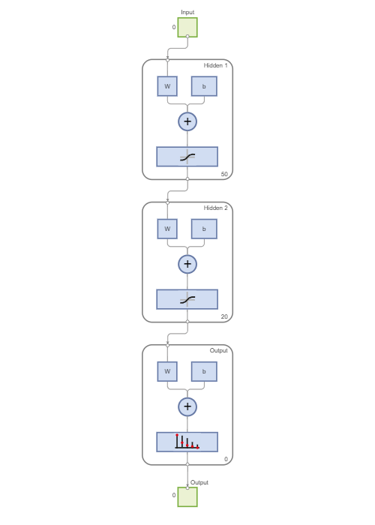

net = patternnet([50,20]); 
% first hidden layer = 50
% second hidden layer = 20
net.trainParam.epochs = 100;
net.trainParam.time = 60;
net.divideParam.trainRatio = 0.9;
net.divideParam.valRatio = 0.1;
net.divideParam.testRatio = 0;
view(net)

 
Computing Resources:
Parallel Workers:
  Worker 1 on B7040311-01, MEX on PCWIN64
  Worker 2 on B7040311-01, MEX on PCWIN64
  Worker 3 on B7040311-01, MEX on PCWIN64
  Worker 4 on B7040311-01, MEX on PCWIN64
  Worker 5 on B7040311-01, MEX on PCWIN64
  Worker 6 on B7040311-01, MEX on PCWIN64
  Worker 7 on B7040311-01, MEX on PCWIN64
  Worker 8 on B7040311-01, MEX on PCWIN64
 


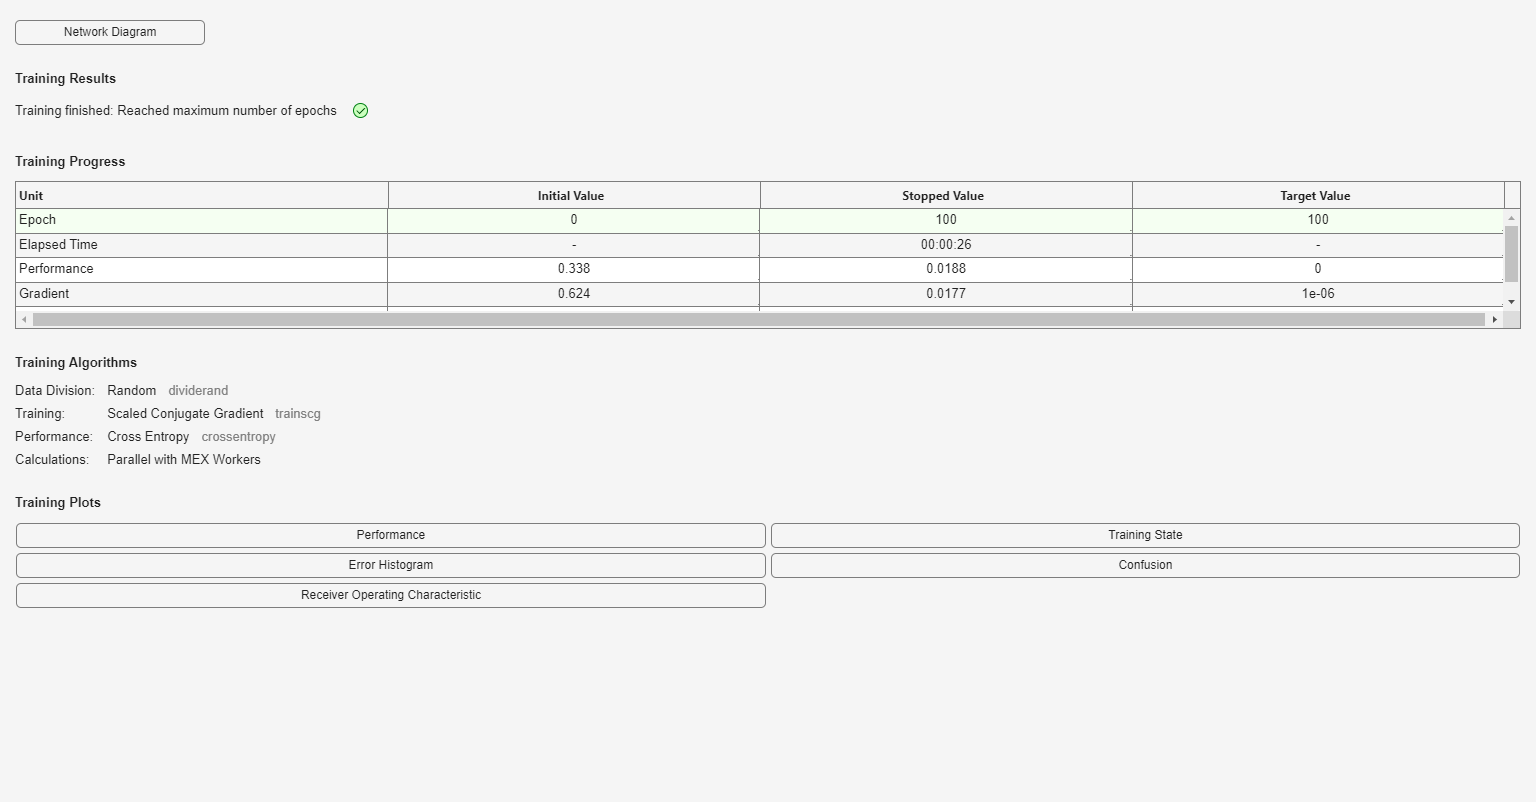

[net,tr] = train(net,X,y, ...
    'useParallel','yes', ...
    'showResources','yes');

pred = net(Xt);
[~,preds] = max(pred);
truth = double(yt);

accuracy = 1 - nnz(truth - preds)/length(truth)

accuracy = 0.9399

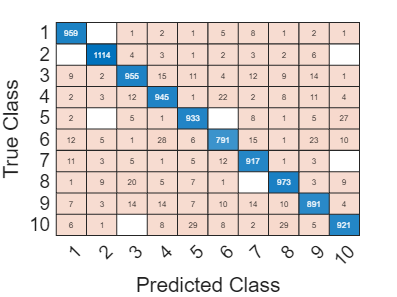

confusionchart(truth,preds)

error_id = find(abs(truth-preds))

error_id =      9    19    34    39    74    93   125   150   152   194   196   218   242   248   252   260   275   283   291   314   321   325   341   353   363   382   392   407   413   422   445   446   449   450   479   496   508   512   532   552   566   583   592   598   620   630   659   660   685   692


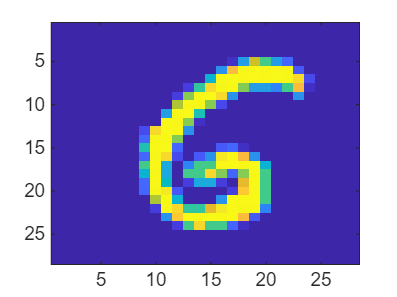

k = error_id(400);
imagesc(reshape(Xt(:,k),28,28))

disp(['True: ' num2str(truth(k)-1) ', pred: ' num2str(preds(k)-1) ', index: ' num2str(k)])

True: 6, pred: 5, index: 4953
